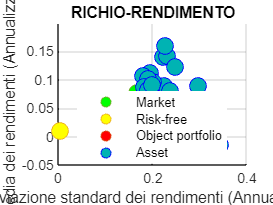

clear
close all
clc

%punto 1 IMPORTA I DATI SU MATLAB
data='25_Portfolios_5x5.txt';
Data=readmatrix(data);
Data_test=[Data(1:end,1)+693960 Data(1:end, 2:end)];

%punto 2 SELEZIONA IL CAMPIONE MENSILE 1/2000 - 1/2010
mdata=Data_test(893:1013,1:26);

%punto 3 STIMA I RENDIMENTI MEDI PER OGNI ASSET, E LA MATRICE DELLE
%VARIANZE-COVARIANZE
MeanReturns=zeros(1,25);
for i=1:25
    MeanReturns(i)=mean(mdata(:,i+1));
end
CovarianceMatrix=cov(mdata(:,2:26));

%punto 4 CREA UN PORTAFOGLIO OBJECT IN MATLAB E DEFINISCI UN PORTAFOGLIO 
% INIZIALE CON PESI UNIFORMI (utilizza come tasso risk-free il valore di 1% annualizzato) 

%openExample('finance/portfolioexamples') FUNZIONE ESEMPLIFICATIVA
load BlueChipStockMoments

%creo il portafoglio object
mret = MarketMean;               %estrapolo dalla BlueChipStockMoments i valori MENSILI
mrsk = sqrt(MarketVar);
cret = 0.000833;                 %ricalcoliamo il riskfree rate dell'1% annuale su base mensile (0.01/12)
crsk = sqrt(CashVar);            %la volatilità si identifica come deviazione standard

%imposto nel port. object RISKFREE=1% NUMERO ASSET = 25 RENDIMENTO MEDIO =
%media dei rendimenti calcolata sui dati di french COVARIANZIA = matrice
%varianza covarianza degli asset french
p = Portfolio('RiskFreeRate',cret, 'NumAssets', 25, 'AssetMean', MeanReturns, 'AssetCovar', CovarianceMatrix);
%lo definisco a parte per sfruttate p.NumAsset altrimenti non definito
p = setInitPort(p,1/p.NumAssets);
%la funzione estimatePortMoments stima la media e la deviazione standard dei 
% rendimenti dei portafogli con pesi uguali. Utilizzabili come benchmark
[ersk,eret] = estimatePortMoments(p,p.InitPort);

%plot dei rischi e rendimenti
s=100;
t=12;
figure('Name','Rischio rendimento asset');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
grid on
title('RICHIO-RENDIMENTO');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Location',"best")
legend('boxoff')
hold off

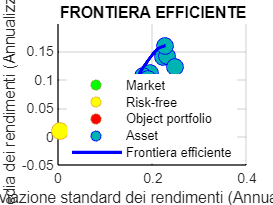


%punto 5 COSTRUISCI UNO STANDARD PORTFOLIO PROBLEM, CON VINCOLI STANDARD, E DISEGNA LA FRONTIERA EFFICIENTE
p = setDefaultConstraints(p);
%la funzione setDefaultConstraints che richiede portafogli completamente investiti in soli titoli 
% (pesi non negativi che devono sommarsi a 1)
pwgt = estimateFrontier(p,500);
%stima 500 portafogli efficienti che determino la frontiera
[prsk,pret] = estimatePortMoments(p,pwgt);

%plot della frontiera
s=100;
t=12;
figure('Name','Frontiera efficiente');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');%depercentualizzati e annualizzati
grid on
title('FRONTIERA EFFICIENTE');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera efficiente','Location',"best")
legend('boxoff')
hold off


%punto 6 QUALE E' IL RANGE DELLE COMBINAZIONI RISCHIO-RENDIMENTO DISPONIBILI?
[rsk,ret] = estimatePortMoments(p,estimateFrontierLimits(p));%determina i valori limite
disp(' ')

disp('Range risk')

Range risk


disp((rsk/100)*sqrt(t))%i valori si riferiscono ai portafogli sulla frontiera efficiente

    0.1485
    0.2279



disp('Range ret')

Range ret


disp((ret/100)*t)

    0.0351
    0.1603



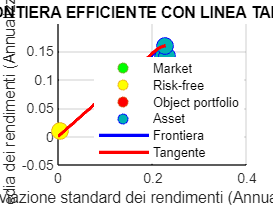


%punto 7 DISEGNA LA LINEA TANGENTE ALLA FRONTIERA EFFICIENTE
%Il teorema di Tobin sui fondi comuni (Tobin 1958) afferma che il problema dell'allocazione 
% del portafoglio è visto come una decisione di allocazione tra un'attività priva di rischio 
% e un portafoglio rischioso. Nel quadro della media-varianza, il contante funge da proxy per 
% un'attività priva di rischio e un portafoglio efficiente sulla frontiera efficiente funge da 
% portafoglio rischioso, in modo tale che qualsiasi allocazione tra il contante e questo
% portafoglio domini tutti gli altri portafogli sulla frontiera efficiente. 
% Questo portafoglio è chiamato portafoglio di tangenza perché si trova nel punto della
% frontiera efficiente in cui la linea tangente che ha origine dall'attività senza rischio
% tocca la frontiera efficiente.
%Dato che l'oggetto Portafoglio ha già il tasso privo di rischio, si può ottenere la retta 
% tangente creando una copia dell'oggetto Portafoglio con un vincolo di bilancio che consente
% di allocare tra lo 0% e il 100% in contanti. Poiché l'oggetto Portafoglio è un oggetto valore, 
% è facile creare una copia assegnando l'output delle funzioni Portafoglio o "set" a una nuova 
% istanza dell'oggetto Portafoglio. Il grafico mostra la frontiera efficiente con le allocazioni
% di Tobin che formano la linea tangente alla frontiera efficiente.

q = setBudget(p,0,1);
qwgt = estimateFrontier(q,500);
[qrsk,qret] = estimatePortMoments(q,qwgt);

figure('Name','Frontiera efficiente con linea tangente');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');%depercentualizzati e annualizzati
plot((qrsk./100).*sqrt(t),(qret./100).*t,'LineWidth',2,'Color','Red');
grid on
title('FRONTIERA EFFICIENTE CON LINEA TANGENTE');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera','Tangente','Location',"best")
legend('boxoff')
hold off

%si noti che la tangente non passa per il "contante" poiché il contante ha un rischio ridotto nei dati

%punto 8 TROVA, SULLA FRONTIERA, PORTAFOGLI:
%       i) CON RENDIMENTO TARGET PARI AL VALORE MEDIANO DEL RANGE DI RENDIMENTI
%       ii) CON UN TARGET DI RISCHIO PARI AL VALORE MEDIANO DEL RANGE DI VOLATILITA'
ordret=sort(MeanReturns); %creo un vettore (sort definisce la tipologia) della media dei rendimenti
ordrsk=sort(sqrt(diag(CovarianceMatrix)));
TargetRet=median(ordret);
medianaret = TargetRet/100*t

medianaret = 0.0829

TargetRsk=median(ordrsk);
medianarisk = TargetRsk/100*sqrt(t)

medianarisk = 0.2224


awgt = estimateFrontierByReturn(p,TargetRet)

awgt =          0
         0
         0
    0.2534
         0
         0
         0
         0
         0
         0


[arsk,aret] = estimatePortMoments(p,awgt);
puntoi_risk = (arsk/100)*sqrt(t)

puntoi_risk = 0.1572

puntoi_ret = (aret/100)*t

puntoi_ret = 0.0829


bwgt = estimateFrontierByRisk(p,TargetRsk)

bwgt =     0.0000
         0
         0
    0.0771
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


[brsk,bret] = estimatePortMoments(p,bwgt);
puntoii_risk = (brsk/100)*sqrt(t)

puntoii_risk = 0.2224

puntoii_ret = (bret/100)*t

puntoii_ret = 0.1588

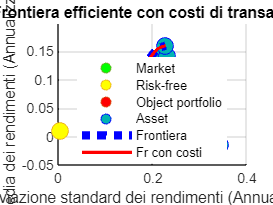


%punto 9  QUALI SONO I PESI DEI PORTAFOGLI TARGET? COMMENTA I TUOI RISULTATI
%Abbiamo ordinato in ordine crescente la media e la varianza dei rendimenti dei 25 portafogli.
%Troviamo i valori target individuando i valori mediani. 
%Tramite la funzione di matlab stimiamo i pesi dei portafogli target.
%Per quanto riguarda al rendimento (punto i) si nota che i pesi si distribuiscono in: 
%       25,34% port.1
%       6,9% port.13
%       1,11% port.21
%       6,9% port.22
%       59,75% port.23
%per quanto riguarda il rischio vediamo che i pesi sono distribuiti:
%       7,71% port.4
%       92,29% port.15

%punto 10  AGGIUNGI COSTI DI TRANSAZIONI PARI A 1BP PER ACQUISTARE E 2BP PER VENDERE.
% DISEGNA LA NUOVA FRONTIERA INSIEME A QUELLA LORDA.

BuyCost=0.0001;
SellCost=0.0002;

q = setCosts(p,BuyCost,SellCost);
qwgt = estimateFrontier(q,500);
[qrsk1,qret1] = estimatePortMoments(q,qwgt);

figure('Name','Frontiera efficiente con costi di transazione');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,':b','LineWidth',5,'Color','Blue');
plot((qrsk1./100).*sqrt(t),(qret1./100).*t,'LineWidth',2,'Color','Red');
grid on
title('Frontiera efficiente con costi di transazione');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera','Fr con costi','Location',"best")
legend('boxoff')
hold off

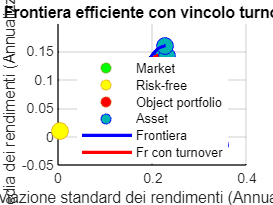


%punto 11 AGGIUNGI UN VINCOLO SUL TURNOVER PARI AL 60%. COME CAMBIANO I TUOI RISULTATI?
% COMMENTA BREVEMENTE E DISEGNA LA NUOVA FRONTIERA.
Turnover = 0.6;
q = setTurnover(q,Turnover);

[qwgt,qbuy,qsell]=estimateFrontier(q,500);
[qrsk2,qret2] = estimatePortMoments(q,qwgt);

figure('Name','Frontiera efficiente con costi di transazione e turnover');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');
plot((qrsk2./100).*sqrt(t),(qret2./100).*t,'LineWidth',2,'Color','Red');
grid on
title('Frontiera efficiente con vincolo turnover');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera','Fr con turnover','Location',"best")
legend('boxoff')
hold off

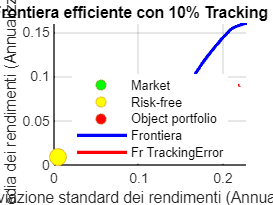


%punto 12 COSTRUISCI UN TRACKING PORTFOLIO, CON PESI UNIFORMI SUI PORTAFOGLI 1,5,10,15,20 e 25.
% FISSA IL TRACKING ERROR AL 10%. DISEGNA LA FRONTIERA VINCOLATA.

ii=[1,5,10,15,20,25];                               % vettore contenete gli indici dei portafogli

TrackingError = 0.1/sqrt(12);                       % 10% annuo, a frequenza mensile
TrackingPort = zeros(25,1);                         %vettore di zeri
TrackingPort(ii) = 1;                               %cambio i valori dei portafogli che seleziono in 1
TrackingPort = (1/sum(TrackingPort))*TrackingPort;  % rendo i pesi uniformi

q = setTrackingError(p,TrackingError,TrackingPort,25); %25 finale è il numassets
qwgt = estimateFrontier(q,500);
[qrsk3,qret3]=estimatePortMoments(q,qwgt);

figure('Name','Frontiera efficiente con la restrizione del 10% di tracking error');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');
plot((qrsk3./100).*sqrt(t),(qret3./100).*t,'LineWidth',2,'Color','Red');
grid on
title('Frontiera efficiente con 10% Tracking Error');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio','Frontiera','Fr TrackingError','Location',"best")
legend('boxoff')
hold off

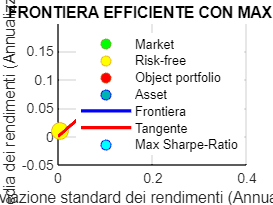


%punto 13 TROVA LO SHARPE RATIO MASSIMO SULLA FRONTIERA CORRISPONDENTE AL PORTAFOGLIO SENZA COSTI
% DI TRANSAZIONE E VINCOLI AL TURNOVER. DISEGNA LA FRONTIERA, LA LINEA TANGENTE E IL PORTAFOGLIO 
% CON IL MASSIMO SR. QUALI SONO I PESI DEL PORTAFOGLIO CON IL MASSIMO SR?

p = setInitPort(p,0); %riprendiamo il portafoglio senza vincoli

swgt = estimateMaxSharpeRatio(p); %usiamo la funzione interna 
[srsk,sret] = estimatePortMoments(p,swgt); %prendiamo i valori

figure('Name','Frontiera efficiente con portafoglio di max sr');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');
plot((qrsk./100).*sqrt(t),(qret./100).*t,'LineWidth',2,'Color','Red');
scatter((srsk/100)*sqrt(t),(sret/100)*t,s,"MarkerEdgeColor","b","MarkerFaceColor","c");
grid on
title('FRONTIERA EFFICIENTE CON MAX SR');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera','Tangente','Max Sharpe-Ratio','Location',"best")
legend('boxoff')
hold off


Blotter = dataset({100*swgt(swgt>0),'Weight'},'obsnames',AssetList(swgt>0));
disp('Portfolio with Maximum Sharpe Ratio')

Portfolio with Maximum Sharpe Ratio


disp(Blotter);

            Weight    
    AA       3.312e-13
    AIG     9.6912e-13
    AXP     1.1158e-12
    BA          36.571
    C       8.3331e-12
    CAT     4.5888e-13
    DD      9.6773e-13
    DIS     8.9578e-12
    GE      1.5506e-12
    GM      1.3114e-12
    HD      5.0649e-13
    HON      1.932e-12
    HPQ     1.2914e-09
    IBM       5.81e-12
    INTC        63.429
    JNJ     8.3213e-13
    JPM      5.305e-12
    KO      4.2247e-12
    MCD     3.3458e-12
    MMM     1.0935e-12
    MO      5.5993e-13
    MRK     1.3079e-12
    MSFT    5.0218e-12
    PFE     5.2917e-13
    PG      3.1536e-13



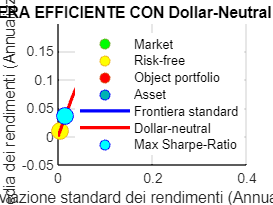


%punto 14 CREA UN DOLLAR-NETRAL INVESTMENT STRATEGY. MOSTRA LA NUOVA FRONTIERA INSIEME
% A QUELLA DEL PORTAFOGLIO STANDARD
Exposure = 1;

q = setBounds(p,-Exposure,Exposure);
q = setBudget(q,0,0);
q = setOneWayTurnover(q,Exposure,Exposure,0);

[qwgt,qlong,qshort] = estimateFrontier(q,500);
[qrsk4,qret4] = estimatePortMoments(q,qwgt);

[qswgt,qslong,qsshort] = estimateMaxSharpeRatio(q);
[qsrsk,qsret] = estimatePortMoments(q,qswgt);

%plot
figure('Name','Frontiera efficiente con Dollar-Neutral Portfolio');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');
plot((qrsk4./100).*sqrt(t),(qret4./100).*t,'LineWidth',2,'Color','Red');
scatter((qsrsk./100).*sqrt(t),(qsret./100).*t,s,"MarkerEdgeColor","b","MarkerFaceColor","c");
grid on
title('FRONTIERA EFFICIENTE CON Dollar-Neutral PORTFOLIO');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera standard','Dollar-neutral','Max Sharpe-Ratio','Location',"best")
legend('boxoff')
hold off

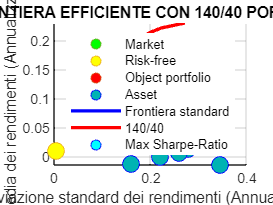


%punto 15 CREA UNA 140/40 FUND STRUCTURE. MOSTRA LA NUOVA FRONTIERA INSIEME 
% A QUELLA DEL PORTAFOGLIO 
Leverage = 0.4;

q = setBounds(p,-Leverage,1+Leverage);
q = setBudget(q,1,1);
q = setOneWayTurnover(q,1+Leverage,Leverage);

[qwgt,qbuy,qsell]=estimateFrontier(q,20);
[qrsk,qret]=estimatePortMoments(q,qwgt);

[qswgt,qslong,qsshort]=estimateMaxSharpeRatio(q);
[qsrsk,qsret] = estimatePortMoments(q,qswgt);

%plot
figure('Name','Frontiera efficiente con 140/40 Portfolio');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');
plot((qrsk./100).*sqrt(t),(qret./100).*t,'LineWidth',2,'Color','Red');
scatter((qsrsk./100).*sqrt(t),(qsret./100).*t,s,"MarkerEdgeColor","b","MarkerFaceColor","c");
grid on
title('FRONTIERA EFFICIENTE CON 140/40 PORTFOLIO');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset','Frontiera standard','140/40','Max Sharpe-Ratio','Location',"best")
legend('boxoff')
hold off

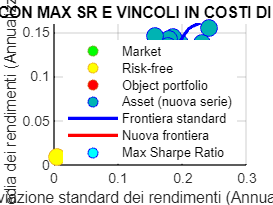


%punto 16 SELEZIONA UN NUOVO CAMPIONE , 1/2010-ULTIMO MESE.
mdata1=Data_test(1013:1165,1:26);

MeanReturns1=zeros(1,25);
for i=1:25
    MeanReturns1(i)=mean(mdata1(:,i+1));
end
CovarianceMatrix1=cov(mdata1(:,2:26));

%punto 17 UTILIZZA COME PORTAFOGLIO INIZIALE QUELLO CORRISPONDENTE AL MASSIMO SR DEL PUNTO
% PRECEDENTE.
%punto 18 MOSTRA LA NUOVA FRONTIERA EFFICIENTE, INSIEME AL PORTAFOGLIO INIZIALE,
% NEL CASO DI COSTI DI TRANSAZIONE PARI AI VALORI INDICATI IN PRECEDENZA E A VINCOLO SUL
% TURNOVER PARI AL 20%.
Turnover2 = 0.2;
p = setInitPort(p, swgt); %p=portafoglio iniziale, swgt=portafoglio con max sr
p = setCosts(p, BuyCost, SellCost); %impostiamo i voncoli dei costi di transazione
p = setTurnover(p, Turnover2); %impostiamo il vincolo del turnover al 20%
p.AssetMean = MeanReturns1';
p.AssetCovar= CovarianceMatrix1;

[pwgt,pbuy,psell]=estimateFrontier(p,500); %calcolo della nuova frontiera
[prsk4,pret4]=estimatePortMoments(p,pwgt);

[pswgt,pslong,psshort]=estimateMaxSharpeRatio(p); %calcolo il portafoglio che massimizza lo sharpe ratio sulla nuova frontiera
[psrsk,psret] = estimatePortMoments(p,pswgt);

%plot
figure('Name','Frontiera efficiente con max sr e vincoli nei costi di transazione e turnover 20%');
scatter(mrsk*sqrt(t),mret*t,s,"MarkerEdgeColor",[0.4660 0.6740 0.1880], "MarkerFaceColor","g");
hold on
scatter(crsk*sqrt(t),cret*t,s,"MarkerEdgeColor",[0.9290 0.6940 0.1250], "MarkerFaceColor","y");
scatter((ersk/100)*sqrt(t),(eret/100)*t,s,"MarkerEdgeColor",[0.8500 0.3250 0.0980], "MarkerFaceColor","r");
scatter((sqrt(diag(p.AssetCovar))./100).*sqrt(t),(p.AssetMean./100).*t,s,"MarkerEdgeColor","b", "MarkerFaceColor",[0 0.7 0.7]);
plot((prsk./100).*sqrt(t),(pret./100).*t,'LineWidth',2,'Color','Blue');
plot((prsk4./100).*sqrt(t),(pret4./100).*t,'LineWidth',2,'Color','Red');
scatter((psrsk/100)*sqrt(t),(psret/100)*t,s,"MarkerEdgeColor","b","MarkerFaceColor","c");
grid on
title('FRONTIERA EFFICIENTE CON MAX SR E VINCOLI IN COSTI DI TRANSAZIONE E TURNOVER');
xlabel('Deviazione standard dei rendimenti (Annualizzata)')
ylabel('Media dei rendimenti (Annualizzato)')
legend('Market','Risk-free','Object portfolio', 'Asset (nuova serie)','Frontiera standard','Nuova frontiera','Max Sharpe Ratio','Location',"best")
legend('boxoff')
hold off